Aplicando a rede neural no motor

modelfile = 'best_model.hdf5';
net = importKerasNetwork(modelfile);

porta = "COM3";
velocidadeComunicacao = 115200;
%velocidadeComunicacao = 74880;
sampleRate = 100;
Ts=1/sampleRate

Ts = 0.0100

plot(net)
title('Network Architecture')

predict(net,[75,   180])

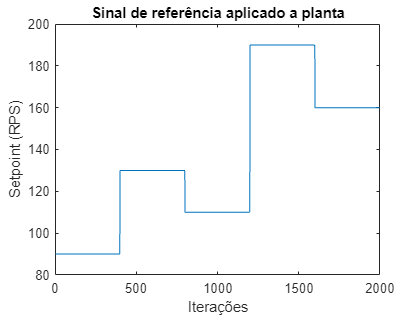

iteracoes = 2000;
setpoint = [iteracoes];

for i = 1 : iteracoes
    if i < iteracoes/5
        setpoint(i) = 90;
        %setpoint(i) = 113;        
    elseif i < 2*iteracoes/5
        setpoint(i) = 130;
        %setpoint(i) = 122;    
    elseif i < 3*iteracoes/5
        setpoint(i) = 110;
        %setpoint(i) = 100;
    elseif i < 4*iteracoes/5
        setpoint(i) = 190;
        %setpoint(i) = 131;
    else 
        setpoint(i) = 160;
        %setpoint(i) = 89;
    end   
end

plot(setpoint)
title('Sinal de referência aplicado a planta')
xlabel('Iterações')
ylabel('Setpoint (RPS)')
ylim([80 200])

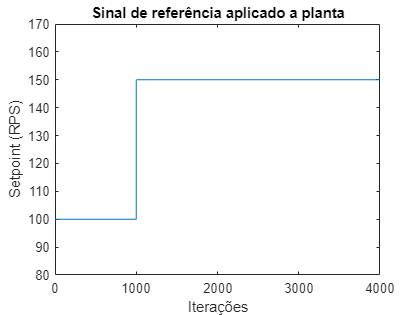

iteracoes = 4000;
setpoint = [iteracoes];

for i = 1 : iteracoes
    if i < iteracoes/4
        setpoint(i) = 100;
        %setpoint(i) = 113;        
    else 
        setpoint(i) = 150;
        %setpoint(i) = 89;
    end   
end

plot(setpoint)
title('Sinal de referência aplicado a planta')
xlabel('Iterações')
ylabel('Setpoint (RPS)')
ylim([80 170])

dado = ([]);
t = ([]);

s = serialport(porta, velocidadeComunicacao);
readline(s);

d = 1;
velocidade = 0;
vanterior = 0;

erro = 0;
erroAnterior = 0;

ierro=0;
ierroAnterior = 0;

degrau = "80";
writeline(s,degrau);
pause(1);
flush(s);

for j = 1:iteracoes

    try 
        dado(j,:) = str2num(readline(s));
        tic;
        if j>1
            velocidade = dado(j,2);
            erro = velocidade-setpoint(j);     
            d = predict(net,[velocidade,setpoint(j),erro]);
        end 
    catch
        tic;
        if j>1
            dado(j,:) = dado(j-1,:);        
            velocidade = dado(j,2);
            erro = velocidade-setpoint(j);
            d = predict(net,[velocidade,setpoint(j),erro]);
        end
    end
      
    duty = round(d);
    vanterior=velocidade;
    erroAnterior=erro;
    ierroAnterior = ierro;
    writeline(s,num2str(duty));
    t(j) = toc;
end

degrau = "0";
writeline(s,degrau);
readline(s);
clear s

temp = mean(t);
fprintf('\n Tempo de processamento: %0.8f\n', temp);


 Tempo de processamento: 0.00221525


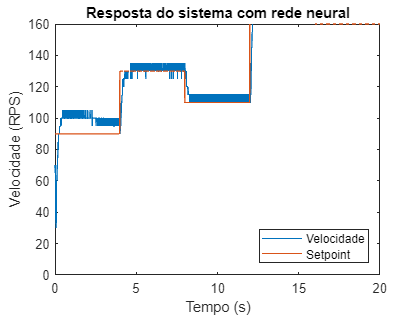

time2 = 0:Ts:iteracoes*Ts-Ts;

plot(time2,dado(:,2))
hold on
plot(time2,setpoint)
hold off
title('Resposta do sistema com rede neural')
xlabel('Tempo (s)')
ylabel('Velocidade (RPS)')
legend('Velocidade', 'Setpoint', "Location", "southeast")
ylim([0 160])

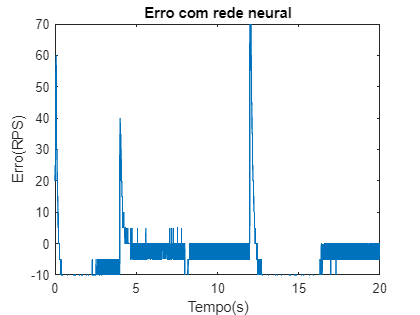



plot(time2, setpoint - dado(:,2)' )
title('Erro com rede neural')
xlabel('Tempo(s)')
ylabel('Erro(RPS)')
ylim([-10 70])

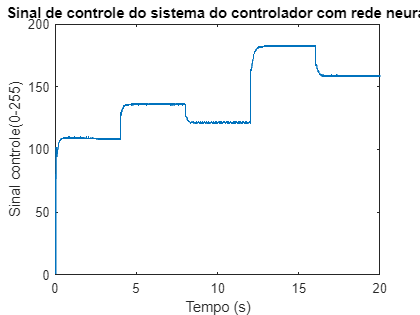


plot(time2,dado(:,1))
title('Sinal de controle do sistema do controlador com rede neural')
xlabel('Tempo (s)')
ylabel('Sinal controle(0-255)')

err = immse(dado(:,2)', setpoint);
fprintf('\n The mean-squared error is %0.4f\n', err);


 The mean-squared error is 113.5125


#### Zerar duty

porta = "COM3";
velocidadeComunicacao = 115200;
%velocidadeComunicacao = 74880;
clear s
s = serialport(porta, velocidadeComunicacao);
str2num(readline(s))

ans =      0     0     0


%readline(s);
degrau = "0";
writeline(s,degrau);
readline(s);
clear s